# Machine Learning with MATLAB

Digital Twin & Automation

# Classification with LDA, QDA

## Data Acquisition

### Dataset 1:  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

clear

%% Train
load("../4weeks_machine_learning_1/CWRU_features/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);


%% Test
load("../4weeks_machine_learning/CWRU_features/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);





#### Plot Test Data

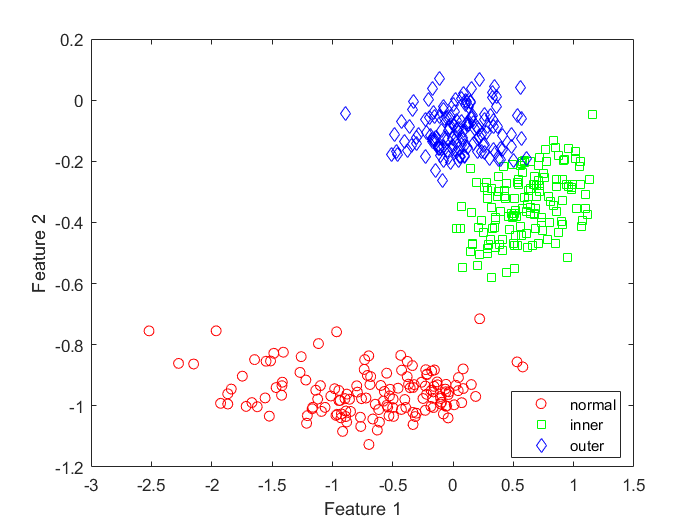

f = figure;
gscatter(X(:, 1), X(:, 2), Y,'rgb','osd');
xlabel('Feature 1')
ylabel('Feature 2')

## Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

# LDA Classification 

fitdiscr()

### Classify with LDA **(Use all Data to train)**

lda = fitcdiscr(X,Y);

### **Anlayze **

**Resubstitution error**:  misclassification error  on the training set.

ldaResubErr = resubLoss(lda)

ldaResubErr = 0.0116

**Confusion matrix** on whole Data set

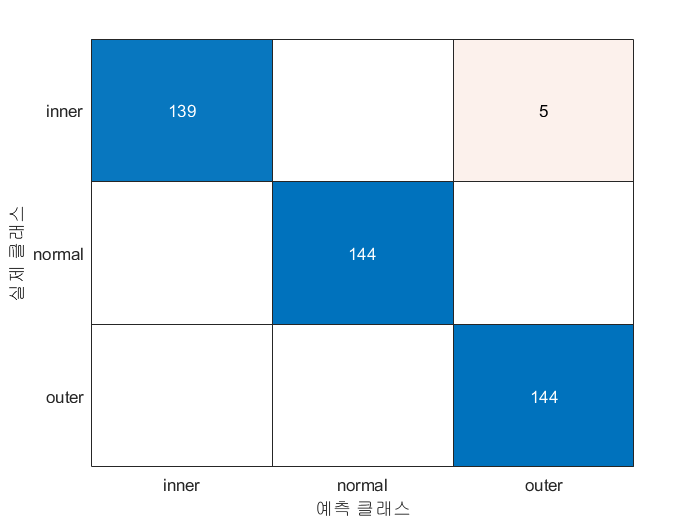

ldaClass = resubPredict(lda);

figure
ldaResubCM = confusionchart(Y,ldaClass);

**Misclassification Plot**

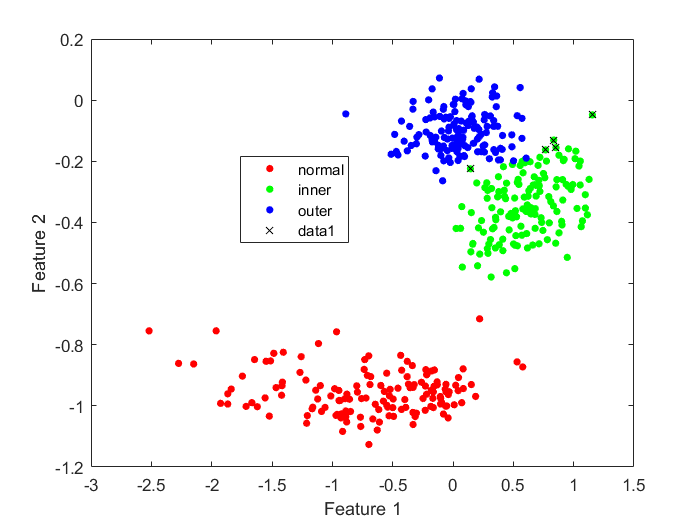

bad = ~strcmp(ldaClass,Y);

figure
gscatter(X(:,1),X(:,2),Y)
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;
xlabel('Feature 1')
ylabel('Feature 2')

**Visualize Separation regions **

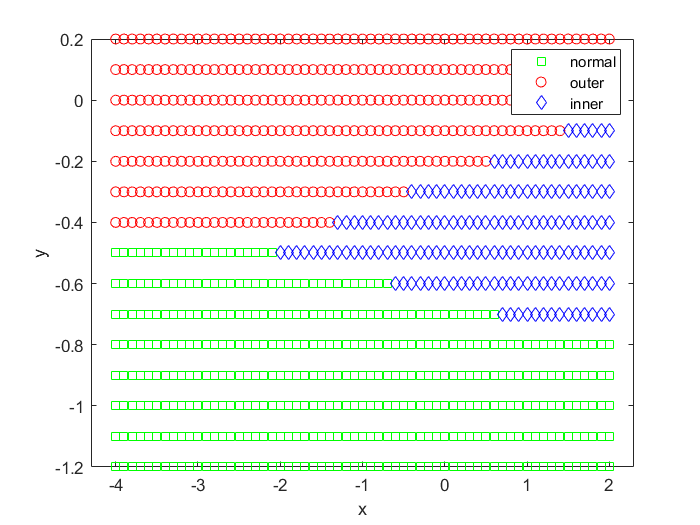

[x,y] = meshgrid(-4:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
j = classify([x y],X,Y);   % classify() for LDA / LQA. use predict(_) otherwise
gscatter(x,y,j,'grb','sod')

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

cvlda = crossval(lda,'CVPartition',cv);
ldaCVErr = kfoldLoss(cvlda)  % loss on validation fold

ldaCVErr = 0.0139

### Classify with LDA (using CV-TrainSet)

% LDA Classify with CV-Train Set  70% Train, 30% Test
cp = cvpartition(N,"HoldOut",0.3);
trainInds = training(cp);
sampleInds = test(cp);
trainingData = X(trainInds,1:2);
sampleData = X(sampleInds,1:2);
trainingLabel= Y(trainInds);
sampleLabel= Y(sampleInds);

[class,err,posterior,logp,coeff] = classify(sampleData,trainingData,trainingLabel);
disp('validation error')

validation error


err

err = 0.0063

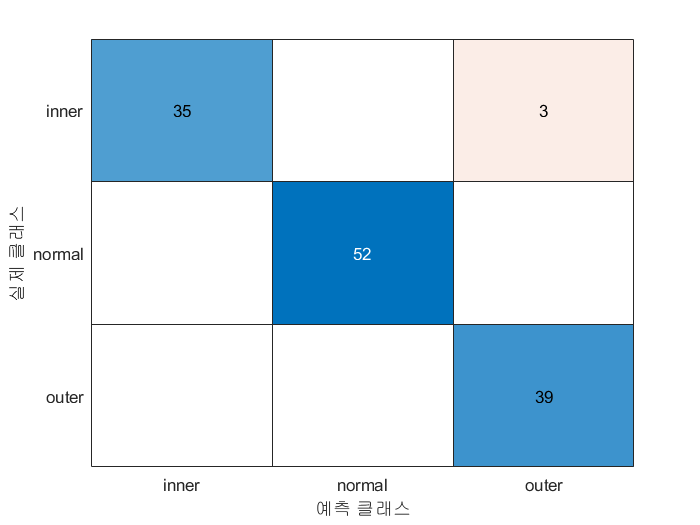


% Validate with CV-Test Set 
cm = confusionchart(sampleLabel,class);

### Predict test data

Predict the classification of test data (Xtest)

%%% YOUR CODE GOES HERE
predictClass = predict(lda,Xtest)

predictClass = 108×1 cell 배열
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


**Calculate the loss  of Test**

%%% YOUR CODE GOES HERE (Xtest,Ytest)
L=loss(lda, Xtest, Ytest)

L = 0.0370

**Plot  Confusion matrix of Test data**

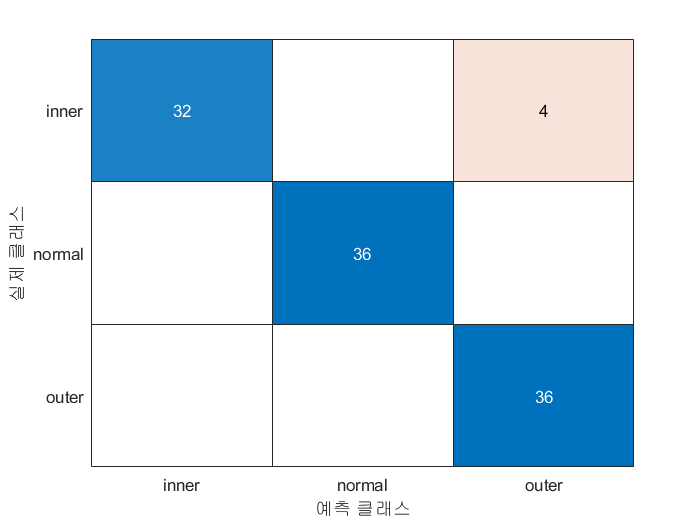

figure

%%% YOUR CODE GOES HERE
resubCM = confusionchart(Ytest,predictClass);

**Plot  Test Results**

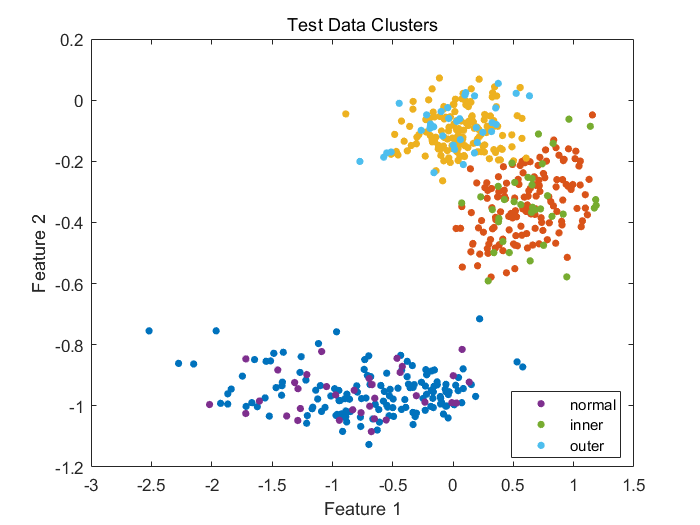

color = lines(6);               % Generate color values
figure
gscatter(X(:,1),X(:,2),Y, color(1:3,:))
hold on
gscatter(Xtest(:,1),Xtest(:,2),Ytest, color(4:6,:))
title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

# LQA Classification 

fitdiscr()

clear

%% Train
load("../4weeks_machine_learning/CWRU_features/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);


%% Test
load("../4weeks_machine_learning/CWRU_features/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

### Fit QDA

qda = fitcdiscr(X,Y,'DiscrimType','quadratic');

### **Anlayze (All Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

%%% YOUR CODE GOES HERE
qdaResubErr = resubLoss(qda)

qdaResubErr = 0.0093

**Confusion matrix** on the training set

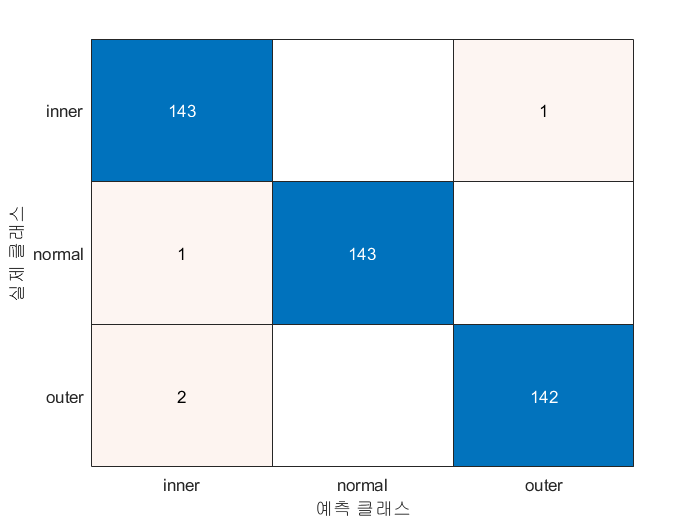

qdaClass = resubPredict(qda);

figure
%%% YOUR CODE GOES HERE
qdaResubCM = confusionchart(Y,qdaClass);

**Misclassification Plot**

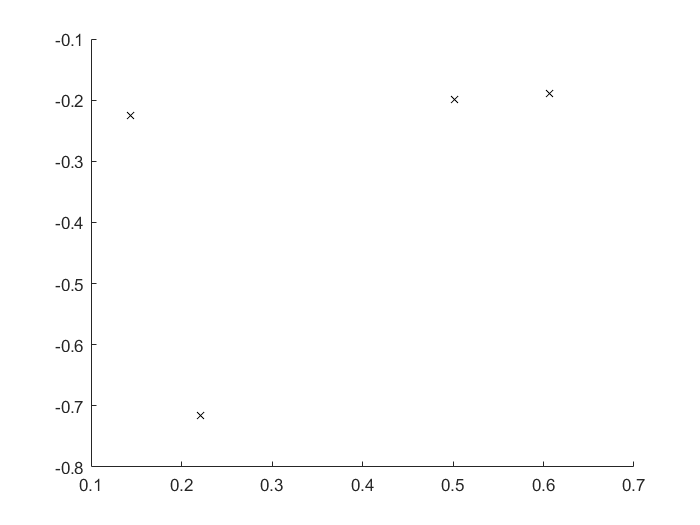

figure()
bad = ~strcmp(qdaClass,Y);
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;

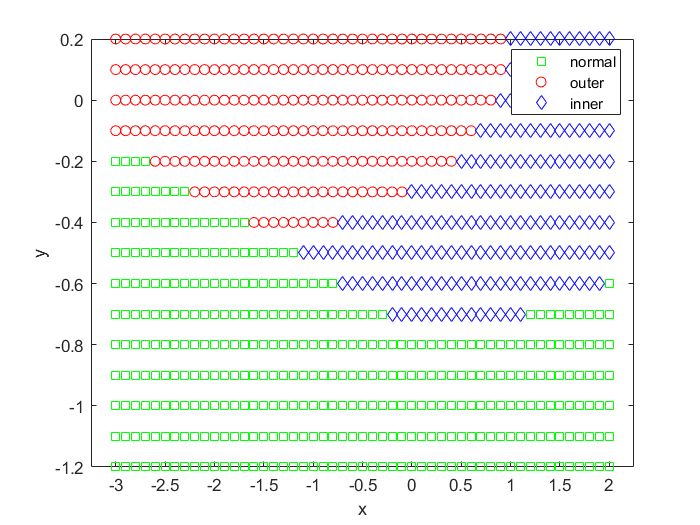

% Visualize Separation regions 
[x,y] = meshgrid(-3:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
j = classify([x y],X,Y,'quadratic');
gscatter(x,y,j,'grb','sod')

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

cvqda = crossval(qda,'CVPartition',cv);

qdaCVErr = kfoldLoss(cvqda)

qdaCVErr = 0.0093

### Predict test data

Predict the classification of test data

%%% YOUR CODE GOES HERE
predictClass_qda = predict(qda,Xtest)

predictClass_qda = 108×1 cell 배열
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


**Calculate the loss  of Test**

%%% YOUR CODE GOES HERE (Xtest,Ytest)
L=loss(qda, Xtest, Ytest)

L = 0

**Plot  Confusion matrix of Test data**

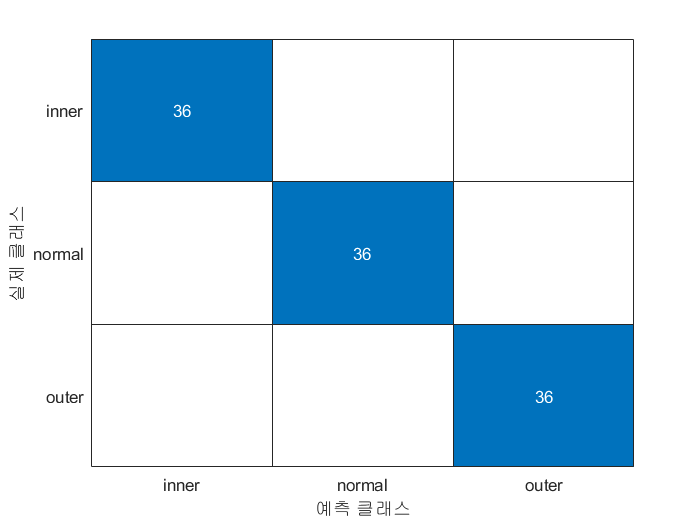

%%% YOUR CODE GOES HERE
 resubCM = confusionchart(Ytest,predictClass_qda);

# Exercise

## Exercise 1: 

Now, Select any 3 features and repeat the process. 

**Features**

clear

 % Example
load("../4weeks_machine_learning/CWRU_features/example_train.mat");
X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);


%% Test
load("../4weeks_machine_learning/CWRU_features/example_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, "kv"));
Xtest(:, 2) = table2array(glob_all_test(:, "mf"));
Xtest(:, 3) = table2array(glob_all_test(:, "cf"));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);

Plot the test and train results in 3D graph.

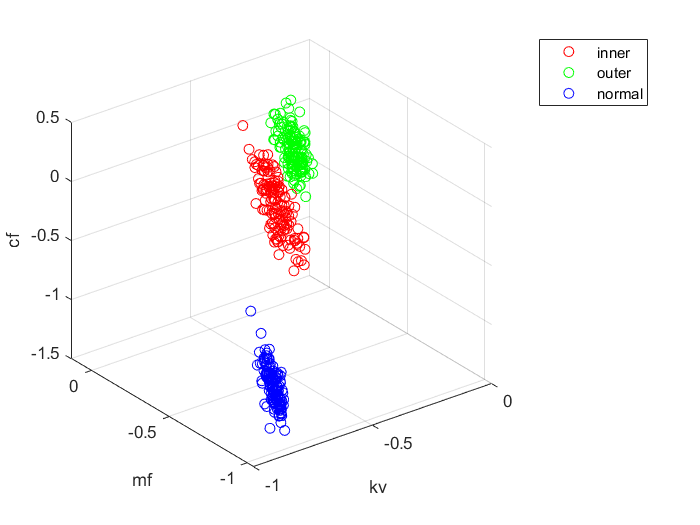

Y_cate = categorical(Y);
idx_inner = Y_cate == 'inner';
idx_outer = Y_cate == 'outer';
idx_normal = Y_cate == 'normal';

figure
plot3(X(idx_inner,1),X(idx_inner,2),X(idx_inner,3),'ro')
hold on
plot3(X(idx_outer,1),X(idx_outer,2),X(idx_outer,3),'go')
plot3(X(idx_normal,1),X(idx_normal,2),X(idx_normal,3),'bo') 
grid on
xlabel('kv')
ylabel('mf')
zlabel('cf')
legend('inner','outer','normal')
hold off

% Your code goes here
lda = fitcdiscr(X,Y);
ldaResubErr = resubLoss(lda)

ldaResubErr = 0

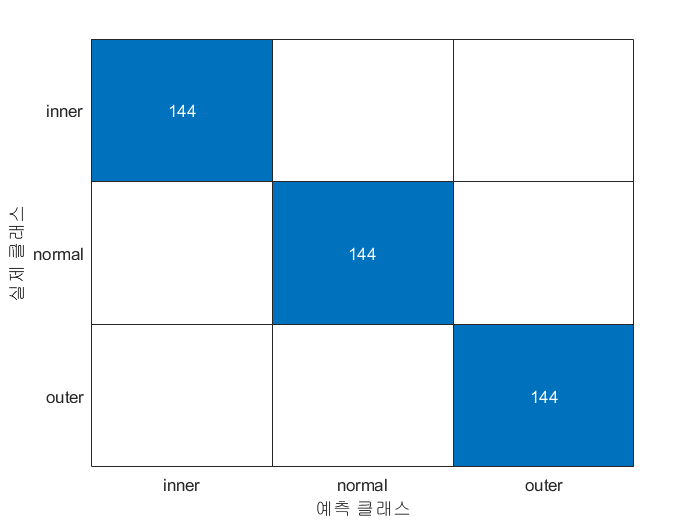


ldaClass = resubPredict(lda);

figure
ldaResubCM = confusionchart(Y,ldaClass);

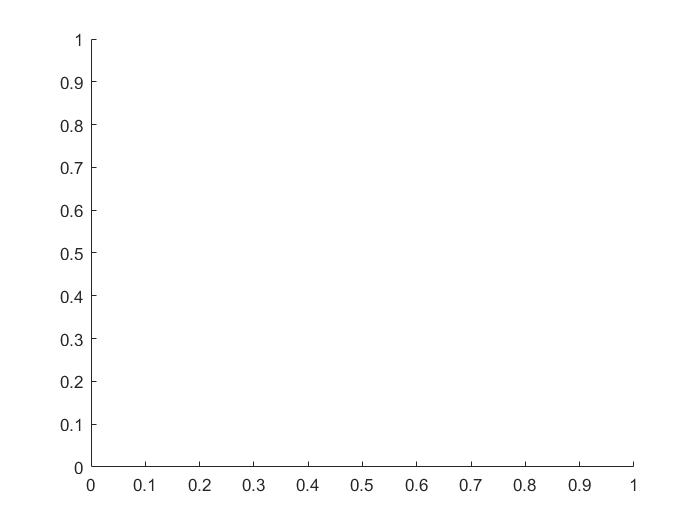

figure()
bad_lda = ~strcmp(ldaClass,Y);
hold on;
plot(X(bad_lda,1), X(bad_lda,2), 'kx');
hold off;

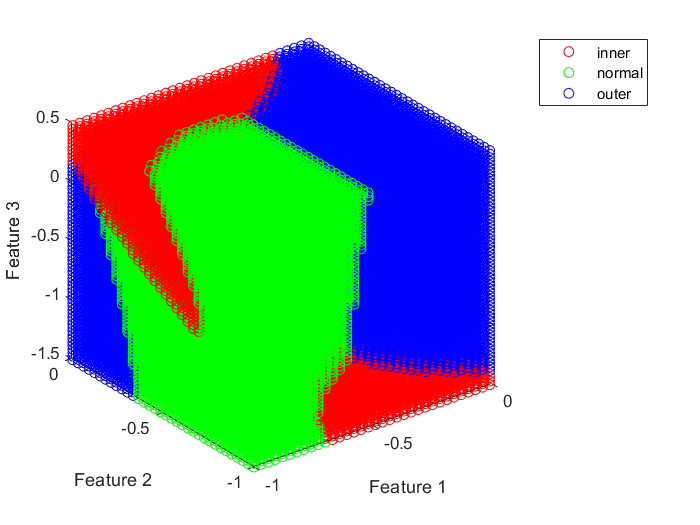


figure()
% Visualize Separation reg5ions
[x,y,z] = meshgrid(-1 : .03 : 0  ,  -1 : .03 : 0  ,  -1.5 : .03 : 0.5);

x = x(:);
y = y(:);
z = z(:);

j_2 = classify([x y z],X,Y,'quadratic');


uniqueGroups_2 = unique(j_2); 
colors = ['r';'g';'b'];


% Plot each group individually: 
for k = 1:length(uniqueGroups_2)
      % Get indices of this particular unique group:
      ind = strcmp(j_2,uniqueGroups_2(k));

      % Plot only this group: 
      plot3(x(ind),y(ind),z(ind), 'o', 'color', colors(k,:))
      hold on
end

legend(uniqueGroups_2);
xlabel('Feature 1');
ylabel('Feature 2');
zlabel('Feature 3');
grid on
hold off

qda = fitcdiscr(X,Y,'DiscrimType','quadratic');
qdaResubErr = resubLoss(qda)

qdaResubErr = 0

% Your code goes here
qdaClass = resubPredict(qda);

figure
qdaResubCM = confusionchart(Y,qdaClass);


figure()
bad_qda = ~strcmp(qdaClass,Y);
hold on;
plot(X(bad_qda,1), X(bad_qda,2), 'kx');
hold off;

## Exercise 2 

Compare performance of Logistic Regression vs LDA vs LQA for CWRU dataset

**Logistic Regression은 두가지 class(1,0)으로 구분할 때 유용한 방법이다. **CWRU dataset에서** normal class를 제외하여 inner와 outer에 대해 분류를 할때 적합하다. Logistic Regression을 이용할 때의 손실은 약 0.0556이다. **

**LDA와 LQA는 class가 여러개 있어도 분류가 가능하다. class가 3개 이상 있을 때 유용한 방법이라고 할 수 있다. LDA와 LQA의 loss는 0으로 Logistic Regression보다 더 정확하다고 할 수있다.**

**하지만 LDA와 LQA를 선정함에 있어서 LDA는 각각의 class가 normal distribution을 가지고있고 covariance가 같은 것을 전재로 한다. **

** covariance: 두 독립변수가 상관관계를 가지고 있다. **

**손실**함수는 **머신러닝**의 현재 성능과 목표값(정답값)을 정량화한 값으로, **머신러닝** 학습이란 **손실**함수 최소화를 의미한다.